clear; clc;
close all;
addpath('../functions', '../data')
load proj23.mat
load rain_rec.mat


% Load data
load transformed2.mat
load BJmodel_light.mat
t_int = ElGeneina.rain_t;
t_org= ElGeneina.rain_org_t;
ndvi = ElGeneina.nvdi;
% rescale the vegitation data so it is between -1 and 1
rendvi = (ndvi/255)*2 -1;
t_ndvi = ElGeneina.nvdi_t;

% Splitting to trainng validation and testingr4e5
t = t_int(793:end);
x = transformed_rain2(793:end)'; % use for model 1 and 2
x = log(x+6); %
y = log(rendvi); %

% data split
trainx = x(1:450);
validx = x(451:551);
testx = x(552:end);


trainn = y(1:450);
validn = y(451:551);
testn = y(552:end) ;

train_t = t(1:450);
valid_t = t(451:551);
test_t = t(552:end);

% Use all data here
y = [trainn;validn];
my = mean(y);
y = y-my;
x = [trainx;validx]; x= x-mean(x);
validstart = train_t(end);
t0 = [train_t;valid_t];

present(MboxJ)

                                                                              
MboxJ =                                                                       
Discrete-time Polynomial model: y(t) = [B(z)/F(z)]u(t) + [1/D(z)]e(t)         
  B(z) = 0.06842 (+/- 0.01051) z^-4                                           
                                                                              
  D(z) = 1 - 0.711 (+/- 0.035) z^-1 - 0.04119 (+/- 0.03462) z^-36             
                                                                              
  F(z) = 1 - 0.8938 (+/- 0.02999) z^-1                                        
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   nb=1   nd=36   nf=1   nk=4  

The D'Agostino-Pearson's K2 test indicates that the NDVI is NORMAL distributed.


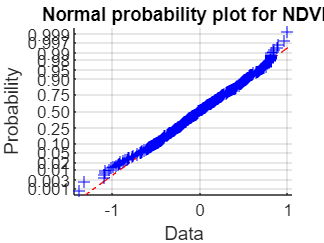

ans = logical
   1


checkIfNormal(y,'NDVI')

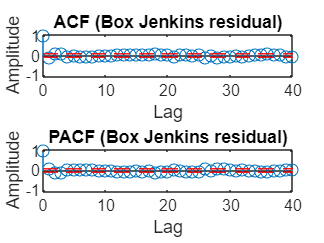

% Box Jenkin's model:
A1 = MboxJ.d;
A2 = MboxJ.f;
B  = MboxJ.b;
C1 = MboxJ.c;

Mi = idpoly(1 ,B, C1, A1 , A2 ) ;
Mi.Structure.F.Free = A2;
Mi.Structure.B.Free = B;
Mi.Structure.D.Free = A1;
%Mi.Structure.C.Free = C1;
z = iddata(y,x);
MboxJ = pem(z,Mi) ;

ehat = resid( MboxJ , z );
plotACFnPACF(ehat.y(50:end),40,'Box Jenkins residual');

checkIfWhite(ehat.y(100:end));

The residual is NOT deemed to be white according to the Monti-test (as 33.17 > 31.41).


varw = var(ehat.y)

varw = 0.0438

The D'Agostino-Pearson's K2 test indicates that the da is NOT normal distributed.


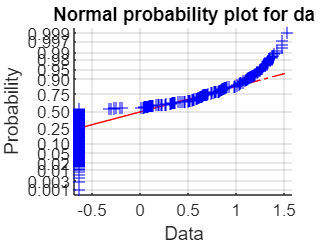

ans = logical
   0


checkIfNormal(x,['da'])

present(MboxJ)

                                                                              
MboxJ =                                                                       
Discrete-time Polynomial model: y(t) = [B(z)/F(z)]u(t) + [1/D(z)]e(t)         
  B(z) = 0.07549 (+/- 0.008024) z^-4                                          
                                                                              
  D(z) = 1 - 0.6654 (+/- 0.03317) z^-1                                        
                                                                              
  F(z) = 1 - 0.8935 (+/- 0.02034) z^-1                                        
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   nb=1   nd=36   nf=1   nk=4  

% Transforming the Box Jenkins model to an ARMAX
KA1 = conv(A1,A2)

KA1 =     1.0000   -1.5589    0.5945         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


KB = conv(B,A1)

KB =          0         0         0         0    0.0755   -0.0502         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


KC = conv(C1,A2)

KC =     1.0000   -0.8935


length(KA1)

ans = 38

length(KB)

ans = 41

length(KC)

ans = 2


% Input model:
A3 = [1 0 0 -0.4637 0 0 0 0 0 0 0 0 0.206 0 0 0 zeros(1,20) -0.4637];
C3 = [1 1.0211 0.9553 zeros(1,9) 0.0419];
%plotACFnPACF(filter(A3,C3,x),38,'input res');
var(filter(A3,C3,x))

ans = 0.0535

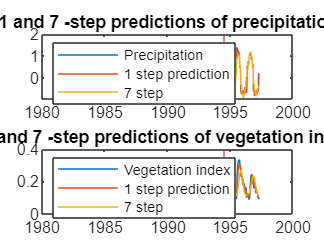


% Predict the output using the found model. (non-adaptive/ polynomial division predictions)
k = 7;
xhatk = zeros(k,length(x));
yhatk = zeros(k,length(y));
for r=1:k
    [Fx, Gx] = polydiv( C3, A3, r );
    xhatk(r,:) = filter(Gx, C3, x);
    [Fy, Gy]   = polydiv( KC, KA1, r );
    [Fhh, Ghh] = polydiv( conv(Fy, KB), KC, r );
    yhatk(r,:) = filter(Fhh, 1, xhatk(r,:)') + filter(Ghh, KC, x) + filter(Gy, KC, y);
    
end

% plot predictions
s1= 1;
s2 = k;
subplot(2,1,1)
plot(t0,x)
hold on
plot(t0,xhatk(s1,:))
plot(t0,xhatk(s2,:))
xline(valid_t(1), '--', 'Color', 'red');
hold off
legend('Precipitation',sprintf('%d step prediction ',s1),sprintf('%d step',s2),Location='northwest')
title(sprintf('%d and %d -step predictions of precipitation',s1,s2))
subplot(2,1,2)
plot(t0,exp(y+my))
hold on
plot(t0,exp(yhatk(s1,:)+my))
plot(t0,exp(yhatk(s2,:)+my))
xline(valid_t(1), '--', 'Color', 'red');
hold off
legend('Vegetation index',sprintf('%d step prediction',s1),sprintf('%d step',s2),Location='northwest')
title(sprintf('%d and %d -step predictions of vegetation index',s1,s2))



eP1    = y(100:end)-yhatk(1,100:end)';
var(eP1)

ans = 0.0422

eP7 = y(100:end)-yhatk(k,100:end)';
var(eP7)

ans = 0.0909

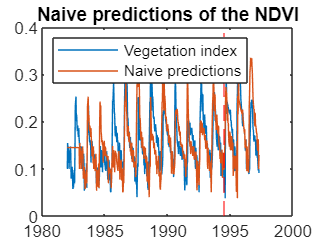

figure;
plot(t0,exp(y+my))
yhat_naive = [zeros(1,35)  y(1:551-35)'];
hold on
plot(t0,exp(yhat_naive+my))

xline(valid_t(1), '--', 'Color', 'red');
hold off
legend('Vegetation index','Naive predictions',Location='northwest')
title('Naive predictions of the NDVI')


pr_er =exp(yhat_naive+my)-exp(y+my);


MSE = 0.0463

Var = 0.1306

MSE = 0.2129

Var = 0.5571


KA = KA1;
KC(3)= 0;
% Initial parameters
InitParam = [ -KA(2) -KA(3) KB(5) KB(6) KC(2)];
InitParam = [0.45, 0.3,0.18,0,0.3];

% Tune the varience of each coefficient:
V= 1e-5;
parameVar = [ 1*V 1*V 1*V 1*V 1*V];

% Set up the Kalman filter:
noPar = length(InitParam);
N = length(y);
maxCoef = 6;
                          % The vector 
xt = zeros(noPar,N);               % Estimated states. Set the initial state to the estimated parameters.
xt(:,maxCoef) = InitParam;


A     = eye(noPar);
Rw    = 1*var(eP1);                                % Measurement noise covariance matrix, R_w. Try using the noise estimate from the polynomial prediction.
Re    =  diag(parameVar);                        % System noise covariance matrix, R_e.
Rx_t1 = 1e-3*diag([1 1 1 1 1]);                        % Initial covariance matrix, R_{1|0}^{x,x}
Rx_k  = Rx_t1;
h_et  = zeros(N,1);                             % Estimated one-step prediction error.
yhat1 = zeros(N,1);                             % Estimated output.
yhat7 = zeros(N,1);
yhatpk = zeros(N,1);
xStd  = zeros(noPar,N);                         % Stores one std for the one-step prediction.
startInd = maxCoef +1;                                   % We use t-38, so start at t=39.


for t=startInd:N-7
    % Update the predicted state and the time-varying state vector.
    x_t1 = A*xt(:,t-1);                         % x_{t|t-1} = A x_{t-1|t-1}    
    C = [ y(t-1) y(t-2) x(t-4) x(t-5) h_et(t-1)];
    yhat1(t) = C*x_t1;
        

    % Update the parameter estimates.
    Ry = C*Rx_t1*C' + Rw;                       % R_{t|t-1}^{y,y} = C R_{t|t-1}^{x,x} + Rw
    Kt = Rx_t1*C'/Ry;                           % K_t = R^{x,x}_{t|t-1} C^T inv( R_{t|t-1}^{y,y} )
    h_et(t) = y(t)-yhat1(t);                    % One-step prediction error, \hat{e}_t = y_t - \hat{y}_{t|t-1}
    xt(:,t) = x_t1 + Kt*( h_et(t) );            % x_{t|t}= x_{t|t-1} + K_t ( y_t - Cx_{t|t-1} ) 

    % Update the covariance matrix estimates.
    Rx_t  = Rx_t1 - Kt*Ry*Kt';                  % R^{x,x}_{t|t} = R^{x,x}_{t|t-1} - K_t R_{t|t-1}^{y,y} K_t^T
    Rx_t1 = A*Rx_t*A' + Re;                     % R^{x,x}_{t+1|t} = A R^{x,x}_{t|t} A^T + Re
    
    % for k step predictions of y_{t+k} we are only allowed to use points
    % up to t and everything after must be estimated. for this we can form
    % the vectors
    yest = [y(1:t) ; zeros(k,1)];
    xest = [x(1:t) ; xhatk(:,t)];
    
    r = 1; % 1 step prediction
    Cp1 =  [ yest(t-1+r) yest(t-2+r) xest(t-4+r) xest(t-5+r) h_et(t-1+r)];
    yest(t+r) = Cp1*xt(:,t);
    
    for r= 2:k
        Cr = [ yest(t-1+r) yest(t-2+r) xest(t-4+r) xest(t-5+r) h_et(t-1+r)];
        yest(t+r) = Cr*A.^(r-1)*xt(:,t);
    end
    yhat7(t+k) = yest(t+k);

    % Estimate a one std confidence interval of the estimated parameters.
    xStd(:,t) = sqrt( diag(Rx_t) );             % This is one std for each of the parameters for the one-step prediction.
end

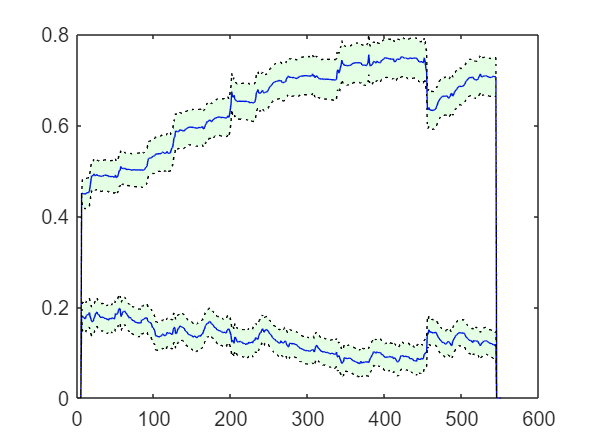

figure
plotWithConf( 1:N, xt', xStd');

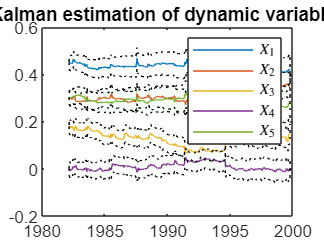

% inspect specific coefficients 
time = t0(maxCoef:N-8);

figure
for r= 1:5
    plot(time,xt(r,maxCoef:N-8)','DisplayName',sprintf('$X_{%d}$',r))
    hold on 
end

for r= 1:5
        data = xt(r,maxCoef:N-8)';
        std = xStd(r,maxCoef:N-8)';
        fill([time ; flipud(time)] , [data-std; flipud(data+std )], 'g', 'FaceAlpha', 0.01, 'LineStyle',':' )
end
hold off
legend('show', '$X_{1}$', '$X_{2}$','$X_{3}$','$X_{4}$','$X_{5}$','Interpreter','Latex');
title('Kalman estimation of dynamic variables')

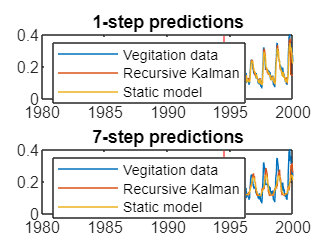

% 1 step predictions
subplot(2,1,1)
plot(t0,exp(y+my))
hold on
plot(t0,exp(yhat1+my))
plot(t0,exp(my+yhatk(1,:)))
xline(valid_t(1), '--', 'Color', 'red');
hold off
title('1-step predictions')
legend('Vegitation data','Recursive Kalman','Static model','Location','northwest')

subplot(2,1,2)
plot(t0,exp(y+my))
hold on
plot(t0,exp(yhat7+my))
plot(t0,exp(yhatk(k,:)+my))
xline(valid_t(1), '--', 'Color', 'red');
hold off
title('7-step predictions')
legend('Vegitation data','Recursive Kalman','Static model','Location','northwest')

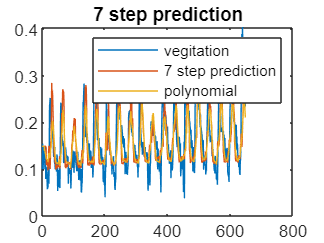

% 7 step predictions
figure
plot(exp(y+my))
hold on
plot(exp(yhat7+my))
plot(exp(yhatk(k,:)+my))
%plot(x*0.1+0.2)
hold off
legend('vegitation','7 step prediction','polynomial')
title('7 step prediction')

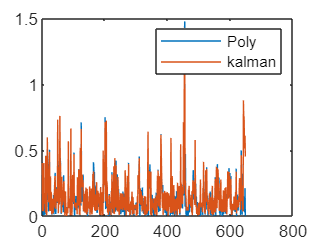

% 1 step residuals:
plot(abs(y-yhatk(1,:)'))
hold on

plot(abs(y-yhat1))
hold off
legend('Poly','kalman')


res_e1 = y-yhat1; % std of 1 step kalman
res_e1 = res_e1(40:N-8);
sum((res_e1')*((res_e1)))/length(res_e1)

ans = 0.0431

res_e = y-yhatk(1,:)'; % std of 1 step polynomial division
res_e = res_e(40:N-8);
sum((res_e'*res_e))/length(res_e)

ans = 0.0419

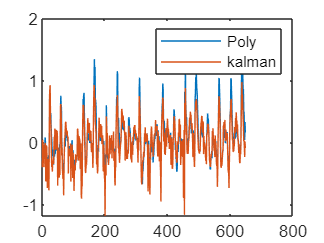

% 7 step residuals:
plot((exp(y)-exp(yhatk(7,:)')))
hold on

plot((y-yhat7))
hold off
legend('Poly','kalman')


res_e7 = y-yhat7; % std of 7 step kalman
res_e7= res_e7(7:N-8);
sum(res_e7'*res_e7)

ans = 73.1989

res_e = y-yhatk(7,:)'; % std of 7 step polynomial division
res_e = res_e(7:N-8);
sum((res_e'*res_e))

ans = 60.7996

% Calculate MSE and var(err) validation data
text= '1 step BJ validation'

text = '1 step BJ validation'

data = exp(y(552:641))-exp(yhatk(1,552:641)');

MSE = (data'*data)/length(data)

MSE = 0.0465

Var = var(data)/var(exp(y(451:551)))

Var = 0.2103

text= '7 step BJ validation'

text = '7 step BJ validation'

data = exp(y(552:641))-exp(yhatk(7,552:641)');
MSE = (data'*data)/length(data)

MSE = 0.2142

Var = var(data)/var(exp(y(552:641)))

Var = 0.6036

% Calculate MSE and var(err)
data = exp(y(451:551))-exp(yhat1(451:551));
text= '1 step Kalman validation'

text = '1 step Kalman validation'

MSE = (data'*data)/length(data)

MSE = 0.0552

Var = var(data)/var(exp(y(451:551)))

Var = 0.2630

text= '7 step Kalman validation'

text = '7 step Kalman validation'

data = exp(y(451:551))-exp(yhat7(451:551));
MSE = (data'*data)/length(data)

MSE = 0.1588

Var = var(data)/var(exp(y(451:551)))

Var = 0.7221


% Calculate MSE and var(err) test 
data = exp(y(552:641))-exp(yhat1(552:641));

MSE = (data'*data)/length(data)

MSE = 0.0405

Var = var(data)/var(exp(y(552:641)))

Var = 0.1254


data = exp(y(552:641))-exp(yhat7(552:641));
MSE = (data'*data)/length(data)

MSE = 0.2574

Var = var(data)/var(exp(y(552:641)))

Var = 0.7514

H = [1 2 ]

H =      1     2


ans =      1     4


[a, b, c, d] = adftest(y)

a = logical
   1


b = 1.0000e-03

c = -7.4623

d = -1.9412

[a, b, c, d] = kpsstest(y)

a = logical
   0


b = 0.0812

c = 0.1292

d = 0.1460

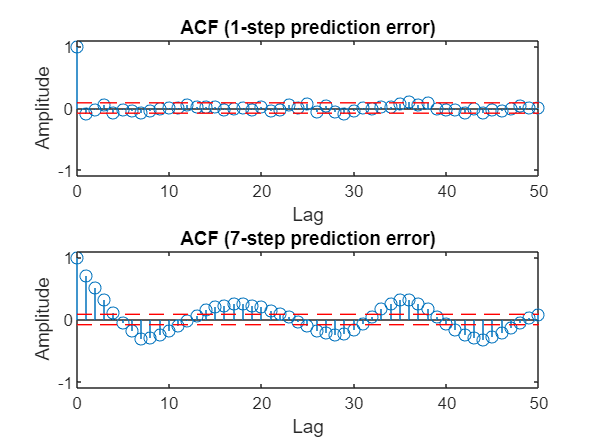

figure
data =  y-yhat1;
subplot(211)
acfEst = acf( data(1:550), 50, 0.05, 1 );
title( sprintf('ACF (%s)','1-step prediction error'))
subplot(212)
data = y-yhat7;
acfEst = acf( data(1:550), 50, 0.05, 1 );
title( sprintf('ACF (%s)','7-step prediction error'))

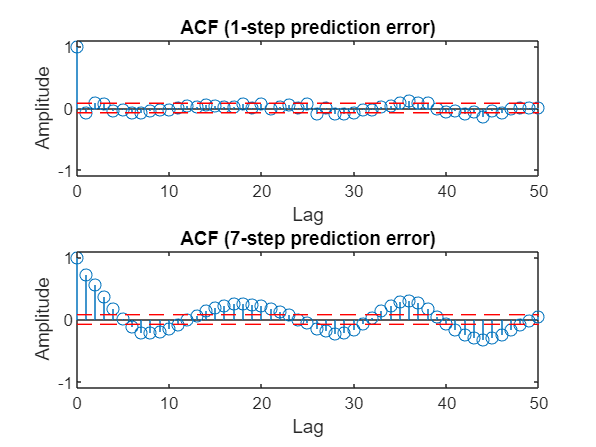

figure
data =  y-yhatk(1,:)';
subplot(211)
acfEst = acf( data, 50, 0.05, 1 );
title( sprintf('ACF (%s)','1-step prediction error'))
subplot(212)
data = y-yhatk(7,:)';
acfEst = acf( data, 50, 0.05, 1 );
title( sprintf('ACF (%s)','7-step prediction error'))

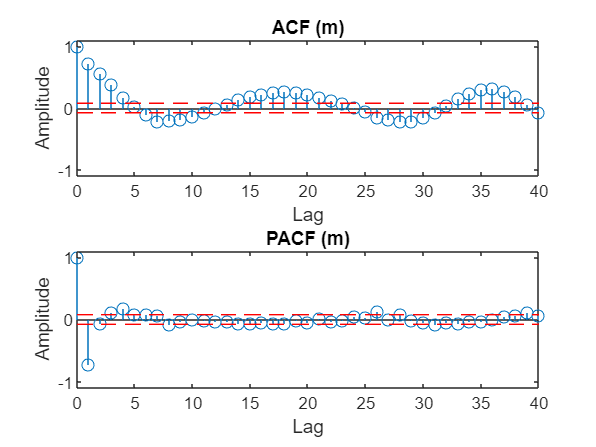

ans =     1.0000
    0.7261
    0.5579
    0.3738
    0.1756
    0.0205
   -0.1129
   -0.2107
   -0.2092
   -0.1879


plotACFnPACF(y-yhatk(7,:)',40,'m');

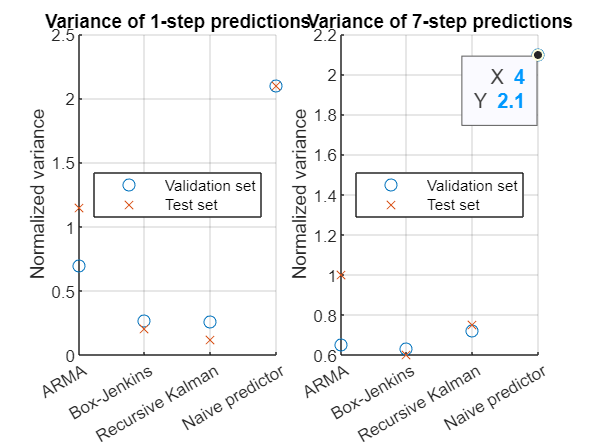

% Sample data (replace with your actual data)
models = {'ARMA', 'Box-Jenkins', 'Recursive Kalman','Naive predictor'};
performance_valid = [0.70 , 0.27, 0.26, 2.1];
performance_test = [1.15, 0.21, 0.12, 2.1];

% Scatter plot
subplot(121)
scatter(1:numel(models), performance_valid, 'o', 'DisplayName', 'Validation set');
hold on;
scatter(1:numel(models), performance_test, 'x', 'DisplayName', 'Test set');
hold off;

% Customize the plot
title('Variance of 1-step predictions');

ylabel('Normalized variance');
xticks(1:numel(models));
xticklabels(models);
legend('Location', 'Best');
grid on;


% Sample data (replace with your actual data)
models = {'ARMA', 'Box-Jenkins', 'Recursive Kalman','Naive predictor'};
performance_valid = [0.65 , 0.63, 0.72, 2.1];
performance_test = [1.0 , 0.60, 0.75, 2.1];

% Scatter plot
subplot(122)
scatter(1:numel(models), performance_valid, 'o', 'DisplayName', 'Validation set');
hold on;
scatter(1:numel(models), performance_test, 'x', 'DisplayName', 'Test set');
hold off;
% Customize the plot
title('Variance of 7-step predictions');

ylabel('Normalized variance');
xticks(1:numel(models));
xticklabels(models);
legend('Location', 'Best');
grid on;